# Control LQI

% Mezclador
clc, clear
syms F tau_x tau_y tau_z K_F K_M L

u_1 = [F; tau_x; tau_y; tau_z];
M = [K_F K_F K_F K_F;
    -L*K_F -L*K_F L*K_F L*K_F;
    -L*K_F L*K_F L*K_F -L*K_F;
    -K_M K_M -K_M K_M];
% u_2 = [omega_1 omega_2 omega_3 omega_4]';
u_2 = M\u_1

$$u\_2 = \left(\begin{array}{c} -\frac{K_{M}\,\tau_{x}+K_{M}\,\tau_{y}-F\,K_{M}\,L+K_{F}\,L\,\tau_{z}}{4\,K_{F}\,K_{M}\,L}\\ \frac{K_{M}\,\tau_{y}-K_{M}\,\tau_{x}+F\,K_{M}\,L+K_{F}\,L\,\tau_{z}}{4\,K_{F}\,K_{M}\,L}\\ \frac{K_{M}\,\tau_{x}+K_{M}\,\tau_{y}+F\,K_{M}\,L-K_{F}\,L\,\tau_{z}}{4\,K_{F}\,K_{M}\,L}\\ \frac{K_{M}\,\tau_{x}-K_{M}\,\tau_{y}+F\,K_{M}\,L+K_{F}\,L\,\tau_{z}}{4\,K_{F}\,K_{M}\,L} \end{array}\right)$$


% Espacio de estados
syms g m I_xx I_yy I_zz K_m omega_0 omega_1

A = zeros(16);
A = sym(A);
A(1:3,4:6) = eye(3);
A(4,8) = g;
A(5,7) = -g;

A(6,13:16) = (2*K_F*omega_0/m)*ones(1,4);
A(10,13:16) = (2*K_F*omega_0*L/I_xx)*[-1 -1 1 1];
A(11,13:16) = (2*K_F*omega_0*L/I_yy)*[-1 1 1 -1];
A(12,13:16) = (2*K_M*omega_1/I_zz)*[-1 1 -1 1];
A(13:16,13:16) = (K_m/(4*K_F*K_M*L))*[K_M*L -K_M -K_M -K_F*L;
                                K_M*L -K_M K_M K_F*L;
                                K_M*L K_M K_M -K_F*L;
                                K_M*L K_M -K_M K_F*L];

A(7:9,10:12) = eye(3);
A(13:16,13:16) = -K_m*eye(4);
A

$$A = \begin{array}{l} \left(\begin{array}{cccccccccccccccc} 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & g & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & -g & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & \sigma_{3} & \sigma_{3} & \sigma_{3} & \sigma_{3}\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & -\sigma_{2} & -\sigma_{2} & \sigma_{2} & \sigma_{2}\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & -\sigma_{1} & \sigma_{1} & \sigma_{1} & -\sigma_{1}\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & -\sigma_{4} & \sigma_{4} & -\sigma_{4} & \sigma_{4}\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & -K_{m} & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & -K_{m} & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & -K_{m} & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & -K_{m} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{2\,K_{F}\,L\,\omega_{0}}{I_{\mathrm{yy}}}\\ \sigma_{2}=\frac{2\,K_{F}\,L\,\omega_{0}}{I_{\mathrm{xx}}}\\ \sigma_{3}=\frac{2\,K_{F}\,\omega_{0}}{m}\\ \sigma_{4}=\frac{2\,K_{M}\,\omega_{1}}{I_{\mathrm{zz}}} \end{array}$$


B = zeros(16,4);
B = sym(B);
%B(6,:) = 1/m*ones(1,4);
%B(10,:) = (2*K_F*omega_0*L/I_xx)*[-1 -1 1 1];
%B(11,:) = (2*K_F*omega_0*L/I_yy)*[-1 1 1 -1];
%B(12,:) = (2*K_M*omega_1/I_zz)*[-1 1 -1 1];
B(13:16,:) = (K_m/(4*K_F*K_M*L))*[K_M*L -K_M -K_M -K_F*L;
                                K_M*L -K_M K_M K_F*L;
                                K_M*L K_M K_M -K_F*L;
                                K_M*L K_M -K_M K_F*L];
B

$$B = \begin{array}{l} \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ \frac{K_{m}}{4\,K_{F}} & -\sigma_{1} & -\sigma_{1} & \sigma_{2}\\ \frac{K_{m}}{4\,K_{F}} & -\sigma_{1} & \sigma_{1} & \frac{K_{m}}{4\,K_{M}}\\ \frac{K_{m}}{4\,K_{F}} & \sigma_{1} & \sigma_{1} & \sigma_{2}\\ \frac{K_{m}}{4\,K_{F}} & \sigma_{1} & -\sigma_{1} & \frac{K_{m}}{4\,K_{M}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{K_{m}}{4\,K_{F}\,L}\\ \sigma_{2}=-\frac{K_{m}}{4\,K_{M}} \end{array}$$


C = zeros(6,16);
C(:,[1 2 3 7:9]) = eye(6);

%[1 3 4 6 7:16]
syms s
transion = s*eye(16) - A;
Gs = simplify(C*(transion\B))

$$Gs = \left(\begin{array}{cccc} 0 & 0 & \frac{2\,K_{m}\,g\,\omega_{0}}{I_{\mathrm{yy}}\,s^{4}\,\left(K_{m}+s\right)} & 0\\ 0 & -\frac{2\,K_{m}\,g\,\omega_{0}}{I_{\mathrm{xx}}\,s^{4}\,\left(K_{m}+s\right)} & 0 & 0\\ \frac{2\,K_{m}\,\omega_{0}}{m\,s^{2}\,\left(K_{m}+s\right)} & 0 & 0 & 0\\ 0 & \frac{2\,K_{m}\,\omega_{0}}{I_{\mathrm{xx}}\,s^{2}\,\left(K_{m}+s\right)} & 0 & 0\\ 0 & 0 & \frac{2\,K_{m}\,\omega_{0}}{I_{\mathrm{yy}}\,s^{2}\,\left(K_{m}+s\right)} & 0\\ 0 & 0 & 0 & \frac{2\,K_{m}\,\omega_{1}}{I_{\mathrm{zz}}\,s^{2}\,\left(K_{m}+s\right)} \end{array}\right)$$

## Variables

clear

g = 9.81; % gravedad
m = 1.6; % masa del dron
% inecia en ejes principales
[I_xx, I_yy, I_zz] = deal(0.021915027, 0.022124548, 0.042349865);
K_F = 7.965; % coeficiente de empuje
K_M = 0.2; % coeficiente de arrastre
L = 0.26; % largo de los brazos
omega_0 = sqrt(m*g/(4*K_F)); % velocidad de motores con dron flotando
omega_1 = sqrt(m*g/(4*K_M)); % velocidad de motores dron rumbo fijo
K_m = log(1-0.9933)/-0.1; % retraso motores

## LQI 16

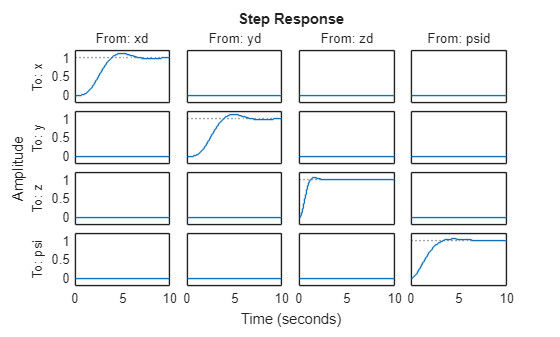

A = zeros(16);
A(1:3,4:6) = eye(3);
A(4,8) = g;
A(5,7) = -g;
A(6,13:16) = 1/m*ones(1,4);
A(10,13:16) = (2*K_F*omega_0*L/I_xx)*[-1 -1 1 1];
A(11,13:16) = (2*K_F*omega_0*L/I_yy)*[-1 1 1 -1];
A(12,13:16) = (2*K_M*omega_1/I_zz)*[-1 1 -1 1];
A(13:16,13:16) = (K_m/(4*K_F*K_M*L))*[K_M*L -K_M -K_M -K_F*L;
                                K_M*L -K_M K_M K_F*L;
                                K_M*L K_M K_M -K_F*L;
                                K_M*L K_M -K_M K_F*L];
A(7:9,10:12) = eye(3);
A(13:16,13:16) = -K_m*eye(4);

B = zeros(16,4);
B(13:16,:) = (K_m/(4*K_F*K_M*L))*[K_M*L -K_M -K_M -K_F*L;
                                K_M*L -K_M K_M K_F*L;
                                K_M*L K_M K_M -K_F*L;
                                K_M*L K_M -K_M K_F*L];

C = zeros(4,16);
C(:,[1 2 3 9]) = eye(4);

D = zeros(size(C,1),4);
sys = c2d(ss(A,B,C,D),1/100);

Q = diag(power([10 10 10 0.1 0.1 0.1 deg2rad([15 15 25 0.1 0.1 0.1]) 0.5 0.5 0.5 0.5 1 1 1 deg2rad(10)],-2));
R = diag(power([20 4 4 4],-2));

AA = [[sys.A;-sys.C] [zeros(size(sys.A,1),size(sys.B,2));eye(size(sys.C,1));]];
BB = [sys.B; zeros(size(sys.B,2),size(sys.B,2))];
[K,~,P] = dlqr(AA,BB,Q,R);
As = AA-BB*K;
Bs = [zeros(size(sys.A,1),size(sys.B,2));eye(size(sys.B,2))];
Cs = [sys.C zeros(size(sys.C,1),size(sys.B,2))];
Ds = zeros(size(sys.C,1),size(sys.B,2));
step(ss(As,Bs,Cs,Ds,1/100, ...
    'StateName',{'x', 'y', 'z', 'vx', 'vy', 'vz', 'phi', 'theta', 'psi', 'p', 'q', 'r', 'omega_1', 'omega_2', 'omega_3', 'omega_4', 'ex', 'ey', 'ez', 'epsi'}, ...
    'InputName', {'xd', 'yd', 'zd', 'psid'}, ...
    'OutputName', {'x', 'y', 'z','psi'}),0:0.01:10)

Cm = zeros(13,16);
Cm(:,[1 2 3 7:16]) = eye(13);
L = place(sys.A',Cm',power(P(1:16),12))';

## LQI 12

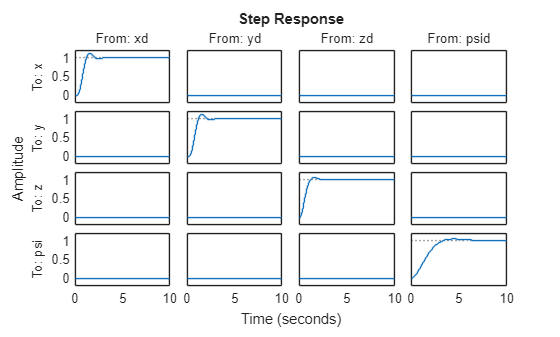

A = zeros(12);
A(1:3,4:6) = eye(3);
A(4,8) = g;
A(5,7) = -g;
A(7:9,10:12) = eye(3);

B = zeros(12,4);
B(6,1) = 1/m;
B(10:12,2:4) = diag(1./[I_xx I_yy I_zz]);

C = zeros(4,12);
C(:,[1 2 3 9]) = eye(4);
D = zeros(size(C,1),4);
sys = c2d(ss(A,B,C,D),1/100);

Q = diag(power([1 1 10 0.1 0.1 0.1 deg2rad([15 15 25 0.1 0.1 0.1]) 0.01 0.01 1 deg2rad(10)],-2));
R = diag(power([1 4 4 4],-2));

AA = [[sys.A;-sys.C] [zeros(size(sys.A,1),size(sys.B,2));eye(size(sys.C,1));]];
BB = [sys.B; zeros(size(sys.B,2),size(sys.B,2))];
[K,~,P] = dlqr(AA,BB,Q,R);
As = AA-BB*K;
Bs = [zeros(size(sys.A,1),size(sys.B,2));eye(size(sys.B,2))];
Cs = [sys.C zeros(size(sys.C,1),size(sys.B,2))];
Ds = zeros(size(sys.C,1),size(sys.B,2));
step(ss(As,Bs,Cs,Ds,1/100, ...
    'StateName',{'x', 'y', 'z', 'vx', 'vy', 'vz', 'phi', 'theta', 'psi', 'p', 'q', 'r','ex', 'ey', 'ez', 'epsi'}, ...
    'InputName', {'xd', 'yd', 'zd', 'psid'}, ...
    'OutputName', {'x', 'y', 'z','psi'}),0:0.01:10)

Cm = zeros(9,12);
Cm(:,[1 2 3 7:12]) = eye(9);
D = zeros(size(Cm,1),4);
save('parametros_LQI.mat', 'sys', 'K', 'Cm', 'D')
%L = place(sys.A',Cm',power(P(1:12),40))';